# Moment of Inertia of a Flat Triangular Plate

We will solve for the center of mass and moment of inertial of a solid, constant density triangular plate.  We place our initial body frame such that $\mathbf{b}_1

$ is parallel to the base of the triangle, with $\mathbf b_2$ pointing up and $\mathbf{b}_3$ normal to the triangle. We define coordinate origin $O$ at the left side of the triangle's base.

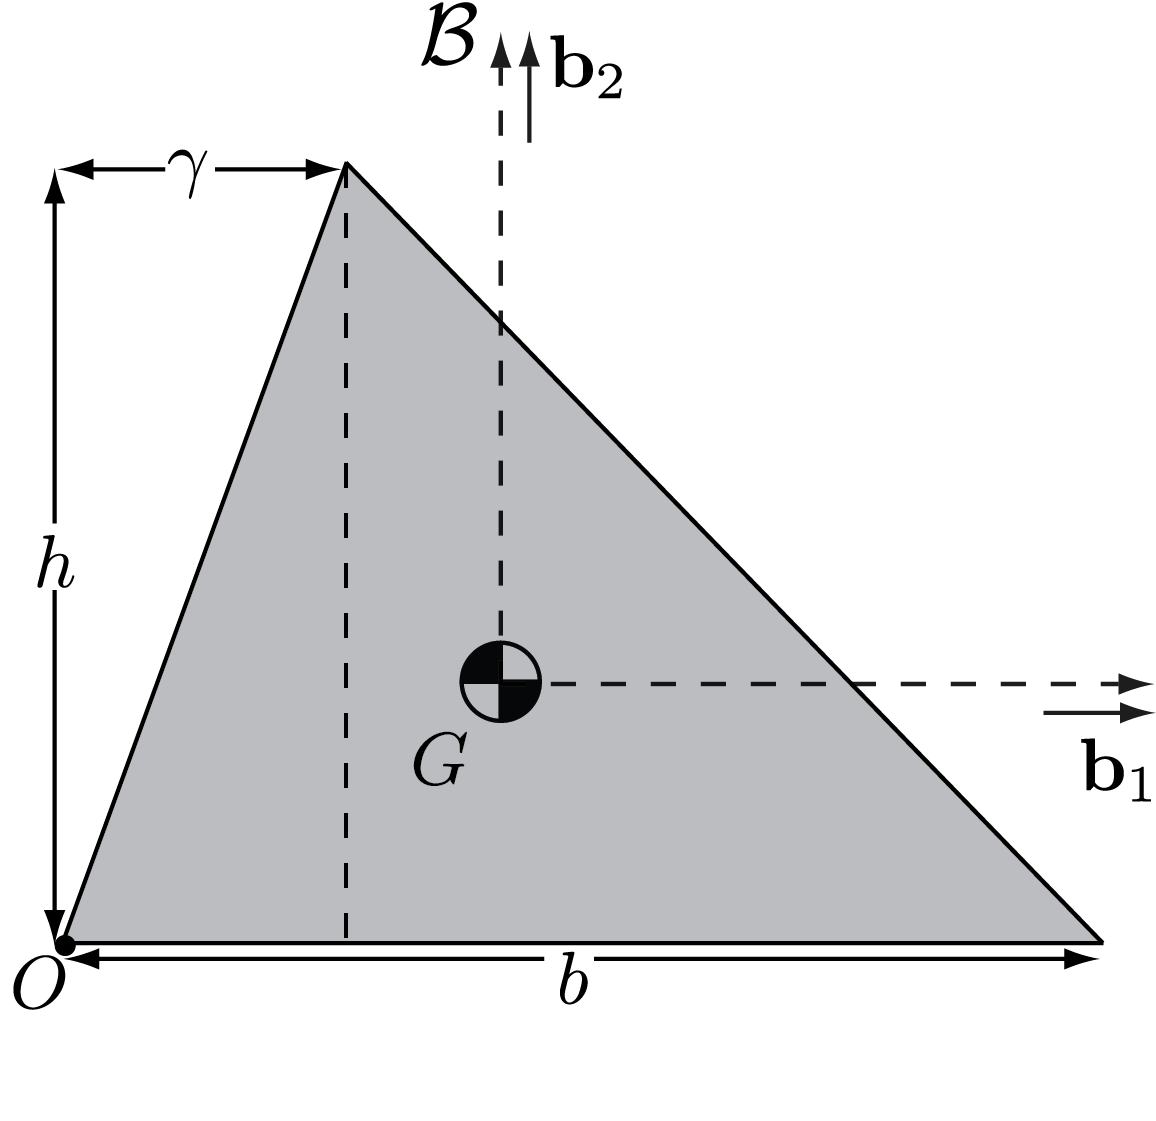

### Center of Mass

We will define the position of our differential mass element with respect to $O$ using Cartesian coordinates, such that $\mathbf r_{\mathrm{d}m/O} = x \mathbf b_1 + y \mathbf b_2$ (the plate is assumed to have neglible thickness and so there is no $\mathbf{b}_3$ component). In order to perform the integration over the full body, we actually need to split into to integrals: one for the part of the triangel to the left of the triangle's altitude (the dashed line) and one for the remaining portion to the right of the altitude.  The left segment of the triangle is defined by the equation $y = \frac{h}{\gamma} x$ while the right segment of the triangle is defined by the equation $y = -\frac{h}{b - \gamma} + h\left(1 + \frac{\gamma}{b - \gamma}\right)$.

% define symbolic variables
syms x y m h b gamma 'positive'

r_dmO = [x;y;0] %Position of dm/O in Cartesian coordinates in the B frame

$$r\_dmO = \left(\begin{array}{c} x\\ y\\ 0 \end{array}\right)$$

leftintegral = int(int(r_dmO, y, [0, h/gamma*x]),x,[0,gamma])

$$leftintegral = \left(\begin{array}{c} \frac{\gamma^{2}\,h}{3}\\ \frac{\gamma \,h^{2}}{6}\\ 0 \end{array}\right)$$

rightintegral = int(int(r_dmO, y, [0, -h/(b-gamma)*x+h*(1+gamma/(b-gamma))]),x,[gamma,b])

$$rightintegral = \left(\begin{array}{c} \frac{h\,\left(b-\gamma \right)\,\left(b+2\,\gamma \right)}{6}\\ \frac{h^{2}\,\left(b-\gamma \right)}{6}\\ 0 \end{array}\right)$$

The center of mass will be the sum of these two integrals, scaled by the areal density ($\rho$) divided by the mass $m$.  As the areal density is the mass divided by the triangle's area, this is equivalent to dividing by the area, which for a triangle is given by $\frac{bh}{2}$.

r_GO = simplify(2/(h*b)*(leftintegral+rightintegral))

$$r\_GO = \left(\begin{array}{c} \frac{b}{3}+\frac{\gamma }{3}\\ \frac{h}{3}\\ 0 \end{array}\right)$$

 The center of mass of the triangle is $\mathbf r_{G/O} = \left(\frac{b}{3}+\frac{\gamma }{3}\right)\mathbf{b}_1 + \frac{h}{3}\mathbf{b}_2$

### Moment of Inertia

Now that we have found the center of mass, we can define $\mathbf r_{\mathrm{d}{m}/G} = \mathbf r_{\mathrm{d}{m}/O} - \mathbf{r}_{G/O} $:

r_dmG = simplify(r_dmO-r_GO)

$$r\_dmG = \left(\begin{array}{c} x-\frac{\gamma }{3}-\frac{b}{3}\\ y-\frac{h}{3}\\ 0 \end{array}\right)$$

The integrand of the moment of inertia tensor is given by $\mathbf r_{\mathrm{d}{m}/O} \cdot \mathbf r_{\mathrm{d}{m}/O}  \mathbb{U} - \mathbf r_{\mathrm{d}{m}/O} \otimes \mathbf r_{\mathrm{d}{m}/O}$. In component form and linear algebraic operations, this is:

integrand = dot(r_dmG,r_dmG)*eye(3) - r_dmG*transpose(r_dmG)

$$integrand = \left(\begin{array}{ccc} {\left(\frac{h}{3}-y\right)}^{2} & -\left(\frac{h}{3}-y\right)\,\left(\frac{b}{3}+\frac{\gamma }{3}-x\right) & 0\\ -\left(\frac{h}{3}-y\right)\,\left(\frac{b}{3}+\frac{\gamma }{3}-x\right) & {\left(\frac{b}{3}+\frac{\gamma }{3}-x\right)}^{2} & 0\\ 0 & 0 & {\left(\frac{b}{3}+\frac{\gamma }{3}-x\right)}^{2}+{\left(\frac{h}{3}-y\right)}^{2} \end{array}\right)$$

As we are using the same coordinates, our integration has the same limits of integration as when we found the center of mass:

leftintegral2 = int(int(integrand, y, [0, h/gamma*x]),x,[0,gamma])

$$leftintegral2 = \begin{array}{l} \left(\begin{array}{ccc} \frac{\gamma \,h^{3}}{36} & \sigma_{1} & 0\\ \sigma_{1} & \frac{\gamma \,h\,\left(2\,b^{2}-4\,b\,\gamma +3\,\gamma^{2}\right)}{36} & 0\\ 0 & 0 & \frac{\gamma \,h\,\left(2\,b^{2}-4\,b\,\gamma +3\,\gamma^{2}+h^{2}\right)}{36} \end{array}\right)\\ \mathrm{where}\\ \sigma_{1}=-\frac{\gamma^{2}\,h^{2}}{72} \end{array}$$

rightintegral2 = int(int(integrand, y, [0, -h/(b-gamma)*x+h*(1+gamma/(b-gamma))]),x,[gamma,b])

$$rightintegral2 = \begin{array}{l} \left(\begin{array}{ccc} \frac{h^{3}\,\left(b-\gamma \right)}{36} & \sigma_{1} & 0\\ \sigma_{1} & \frac{h\,\left(b^{3}-\sigma_{4}+5\,b\,\gamma^{2}-3\,\gamma^{3}\right)}{36} & 0\\ 0 & 0 & \frac{b\,h^{3}}{9}+\frac{b^{3}\,h}{9}-\frac{\gamma \,h^{3}}{9}-\frac{\gamma^{3}\,h}{9}+\frac{2\,b^{3}\,h^{3}}{9\,\sigma_{2}}-\frac{2\,\gamma^{3}\,h^{3}}{9\,\sigma_{2}}-\frac{b^{4}\,h}{12\,\left(b-\gamma \right)}-\frac{\gamma^{4}\,h}{36\,\left(b-\gamma \right)}-\frac{b^{4}\,h^{3}}{12\,\sigma_{3}}-\frac{\gamma^{4}\,h^{3}}{12\,\sigma_{3}}-\frac{2\,b^{2}\,h^{3}}{9\,\left(b-\gamma \right)}-\frac{2\,\gamma^{2}\,h^{3}}{9\,\left(b-\gamma \right)}+\frac{2\,b\,\gamma^{2}\,h}{9}-\frac{2\,b^{2}\,\gamma \,h}{9}+\frac{b\,\gamma^{3}\,h^{3}}{3\,\sigma_{3}}+\frac{b^{3}\,\gamma \,h^{3}}{3\,\sigma_{3}}-\frac{2\,b^{2}\,\gamma^{2}\,h}{9\,\left(b-\gamma \right)}-\frac{b^{2}\,\gamma^{2}\,h^{3}}{2\,\sigma_{3}}+\frac{2\,b\,\gamma^{2}\,h^{3}}{3\,\sigma_{2}}-\frac{2\,b^{2}\,\gamma \,h^{3}}{3\,\sigma_{2}}+\frac{4\,b\,\gamma \,h^{3}}{9\,\left(b-\gamma \right)}+\frac{b\,\gamma^{3}\,h}{9\,\left(b-\gamma \right)}+\frac{2\,b^{3}\,\gamma \,h}{9\,\left(b-\gamma \right)} \end{array}\right)\\ \mathrm{where}\\ \sigma_{1}=\frac{h^{2}\,{\left(b-\gamma \right)}^{2}}{72}\\ \sigma_{2}=b^{2}-2\,b\,\gamma +\gamma^{2}\\ \sigma_{3}=b^{3}-\sigma_{4}+3\,b\,\gamma^{2}-\gamma^{3}\\ \sigma_{4}=3\,b^{2}\,\gamma \end{array}$$

Finally, the moment of inertia matrix is equal to the sum of these integrals scaled by the areal density (which is mass divided by the previously found area):

I_G = m/(h*b/2)*simplify(leftintegral2+rightintegral2)

$$I\_G = \left(\begin{array}{ccc} \frac{h^{2}\,m}{18} & \frac{h\,m\,\left(b-2\,\gamma \right)}{36} & 0\\ \frac{h\,m\,\left(b-2\,\gamma \right)}{36} & \frac{m\,\left(b^{2}-b\,\gamma +\gamma^{2}\right)}{18} & 0\\ 0 & 0 & \frac{m\,\left(b^{2}-b\,\gamma +\gamma^{2}+h^{2}\right)}{18} \end{array}\right)$$